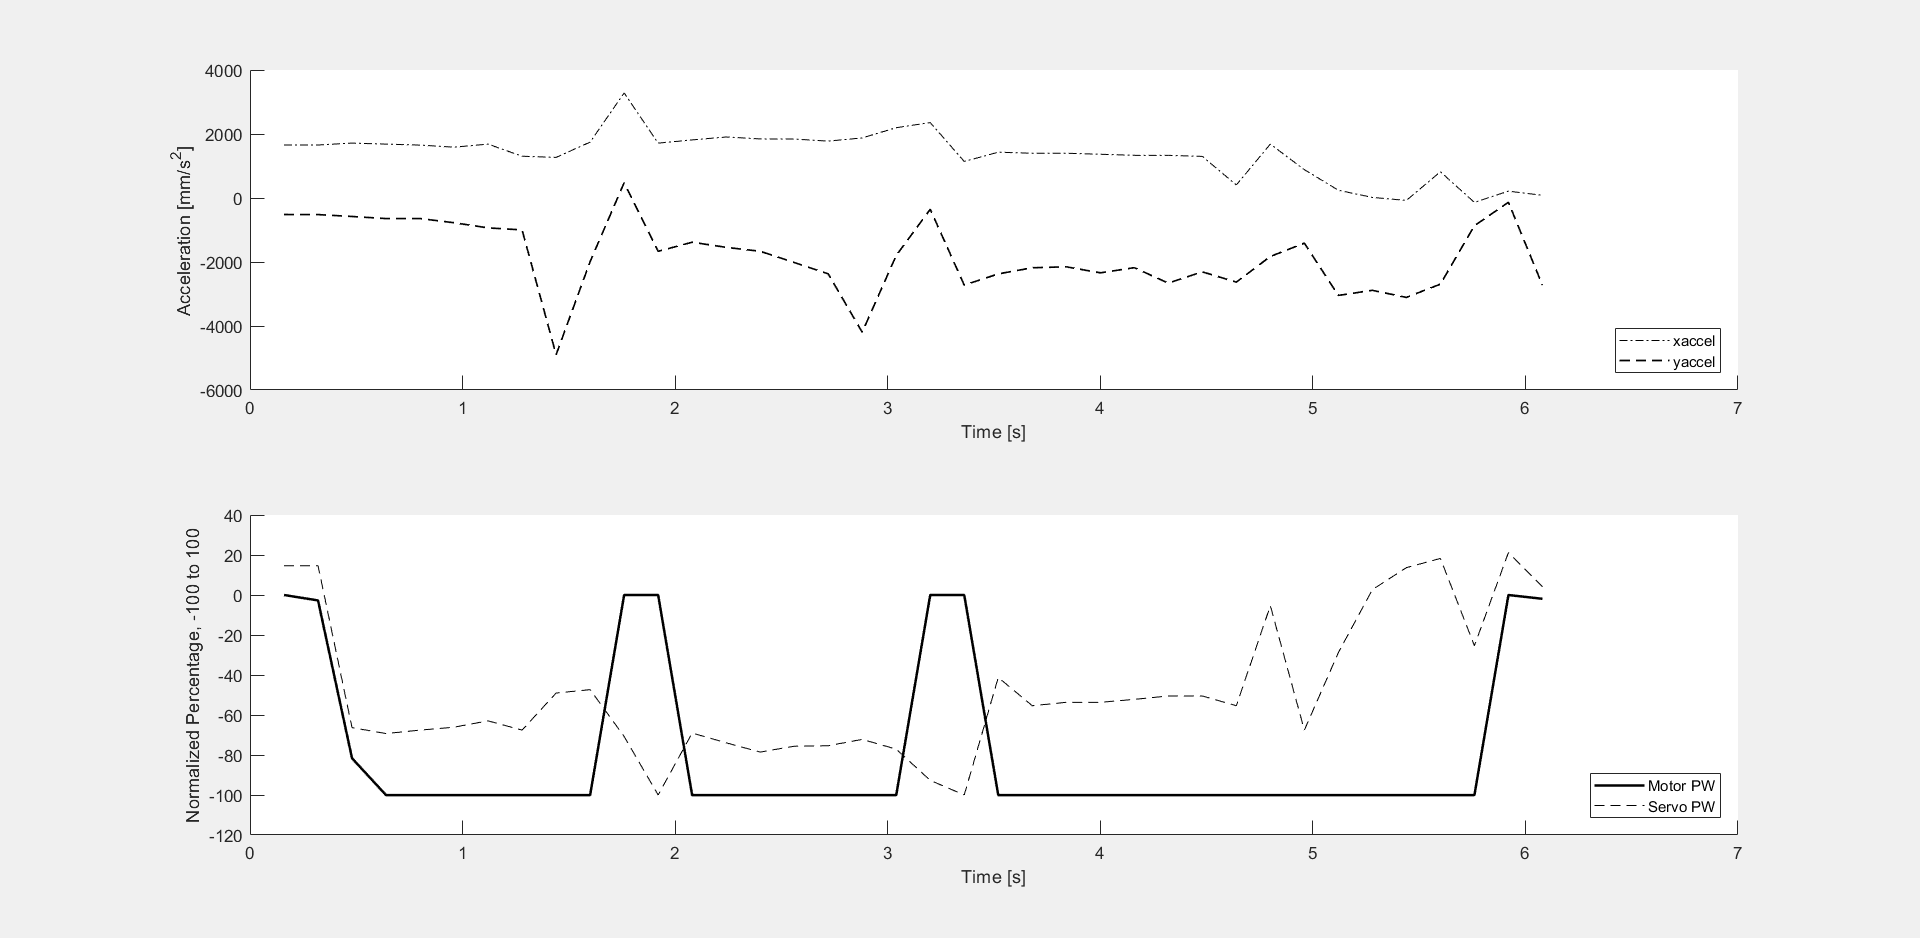

data = allthedata01; %Change data number for different graph
x = 1:size(data,1);
x = x*.160;

data(:,5) = (data(:,5) - 2765)/(3502 - 2027)*200;
data(:,4) = (data(:,4) - 2835)/(3245 - 2425)*200;

close all
figure('Name','Data','NumberTitle','Off')
set(gcf,'Visible','on') %Automatically pop out the figure
clf
subplot(2,1,1)
hold on;
plot(x,data(:,1),'-.k');
plot(x,data(:,2),'--k','LineWidth',1);
xlabel('Time [s]')
ylabel('Acceleration [mm/s^2]')
legend('xaccel','yaccel','Location','southeast')

subplot(2,1,2)
hold on;
plot(x,data(:,5), '-k','LineWidth',1.5);
plot(x,data(:,4),'--k');
xlabel('Time [s]')
ylabel('Normalized Percentage, -100 to 100')
legend('Motor PW','Servo PW','Location','southeast')